A = 0.5*rand(4,3)

A =     0.3446    0.1145    0.2692
    0.3741    0.4567    0.4981
    0.2253    0.0762    0.0391
    0.0419    0.4129    0.2213


A12 = A(1,2)

A12 = 0.1145

A23 = A(2,3)

A23 = 0.4981

B = diag([3,3,3,3])

B =      3     0     0     0
     0     3     0     0
     0     0     3     0
     0     0     0     3


A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


b = [1;2;3]

b =      1
     2
     3


A\b

ans =     0.0500
    0.3000
    0.0500


eig(A)

ans =    15.0000
    4.8990
   -4.8990


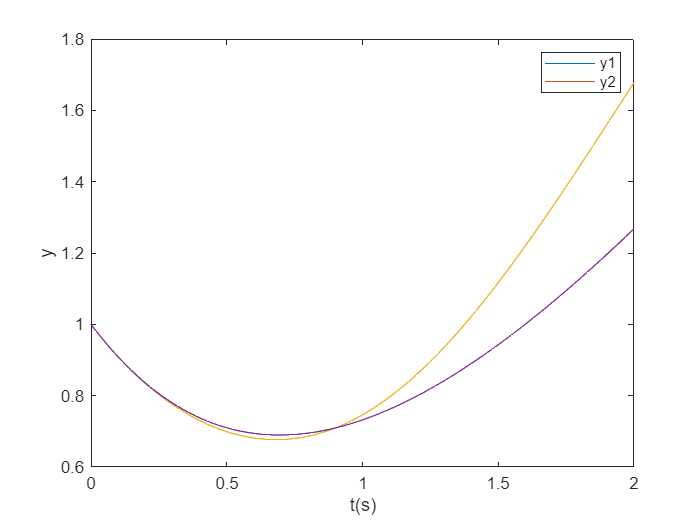

delta_t = 0.01;
tf=2;
t = 0:delta_t:tf;
y1_dot = zeros(length(t),1);
y1 = zeros(length(y1_dot),1);
y1(1)=1;
y2_dot = y1_dot;
y2 = y1;
for i=1:length(t)-1
    y1_dot(i) = t(i)^2-y1(i)^2;
    y1(i+1) = y1(i)+y1_dot(i)*delta_t;
    y2_dot(i) = t(i)-abs(y2(i));
    y2(i+1) = y2(i)+y2_dot(i)*delta_t;
end

figure(1);
plot(t,y1);
hold on
plot(t,y2);
xlabel('t(s)');
ylabel('y');
legend('y1','y2');